clc
clear
%declare variables
g = 9.8; % gravity
rR = 0.06; %Radius of Reaction Wheel
l = 0.133; %Lenght of rod - 0.133 for bike
mM = 0.11; %mass of motor  0.11
mP = 0.027; % mass of pendulum rod in kg.  0.027
mR = 0.06; %mass of Reaction wheel   0.06
M = 0.5*mP + mR; %used for convenience
IR = (0.5)*mR*(rR^2); %moment of intertia of reaction wheel as it spins
Im = mM*(l^2); % moment of inertia of rod due to motor as its attached to the end of the rod
IRW = mR*(l^2); % the reaction wheel is also setting on top of the rod so its mass must be accounted for
Ip = (1/3)*mP*(l^2); %moment of inertia of rod due to its own mass
I = Ip + IRW; %Total moment of inertia of rod due to the 3 masses (mM, mP, mR)
kt = 0.3568; %Torque constant. I guessed it. The value can be anywhere from 0.05 to 0.2
ke = 0.4105; %also guessed
R = 2.5; %Internal resistance of motor anywhere from 0.1 to 1 ohm
induct = 0.499; %inductance of motor could be anywhere form 0.00001 to 0.00005

%create state space matracies
A = [0 1 0 0; ((M*g)/l) 0 0 (-kt/I); 0 0 0 (kt/IR); 0 0 (-ke/induct) (-R/induct)];
B = [0; 0; 0; (1/induct)];
%C = [ 1 0 0 0; 0 1 0 0; 0 0 1 0];
C = [ 1 0 0 0];
D = 0;
% create a steate space model object called sys
sys = ss(A,B,C,D);

t = 0:0.01:0.27; % Time vector for simulation
u = 12*ones(size(t)); % Input signal (step input) in volts

% Initial condition for the pendulum angle (theta) in radians
initial_condition = [0.122173; 0; 0; 0]; % 0.12 rads initial pos

% Simulate the step response with the given initial condition
[y, t] = lsim(sys, u, t, initial_condition);

%[y,t] = step(sys,t);
%var = step(sys,t);

%convert output from rad to deg
y_degrees = rad2deg(y);
% get step response and save it into y and t
%[y, t] = lsim(sys, u, t);

[n,d] =ss2tf(A,B,C,D) %num and den of transfer function

n =          0         0         0 -585.8304         0


d = 1.0e+04 *

    0.0001    0.0005    0.2712   -0.0027   -1.4719


G = tf(n,d) %transfer func

G =
 
                     -585.8 s
  ----------------------------------------------
  s^4 + 5.01 s^3 + 2712 s^2 - 27.13 s - 1.472e04
 
Continuous-time transfer function.



[C_pid,info] = pidtune(G,'PID') %tune pid

C_pid =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = -20.5, Ki = -41.7
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 3.5869
           PhaseMargin: 60.0000


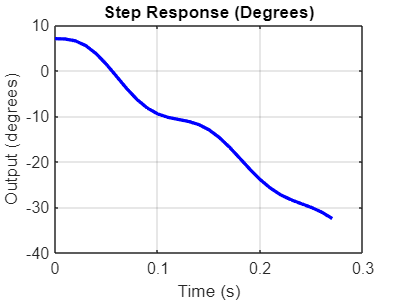


%graphing. you can copy this into the command window if you want
% Plot the step response
%plot(t, y_degrees);
%xlabel('Time S');
%ylabel('Output');
%title('Step Response');
%grid on;


% Plot the step responses in degrees with legends
plot(t, y_degrees(:,1), 'b', 'LineWidth', 2); % Blue line for the first output
hold on; % Hold the current plot
%plot(t, y_degrees(:,2), 'g', 'LineWidth', 2); % Green line for the second output
%plot(t, y_degrees(:,3), 'r', 'LineWidth', 2); % Red line for the third output
xlabel('Time (s)');
ylabel('Output (degrees)');
title('Step Response (Degrees)');
grid on;


% Add legends for each output
%legend('Theta_P', 'Thetadot_P', 'Thetadot_R');